# load the data

T = readtable('data_29749.csv');

## The order of the data is

% (time,x,y,speed,theta,u,delta)
time = T{:,1};
x = T{:,2};
y = T{:,3};
speed = T{:,4};
theta = T{:,5};
u = T{:,6};
delta = T{:,7};

% create the input and output matrices

output = {x(1:300),y(1:300),speed(1:300)};
output = cell2mat(output);


input = {u(1:300),delta(1:300)};
input = cell2mat(input);

% Create iddata object

data = iddata(output,input,0.05);
data.OutputName ={'x';'y';'speed'};
data.InputName ={'u';'delta'};

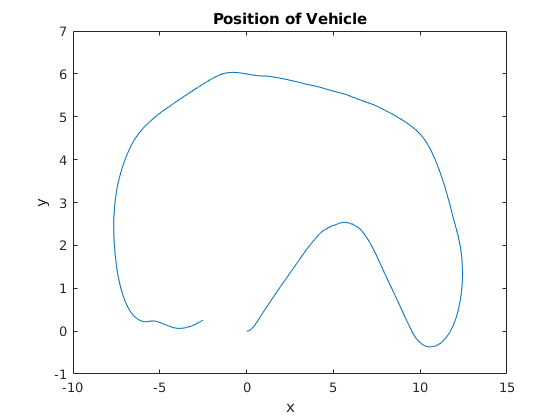

% Let's look at the postion data we have
figure();
plot(x(1:300),y(1:300));
xlabel('x') 
ylabel('y') 
title("Position of Vehicle")

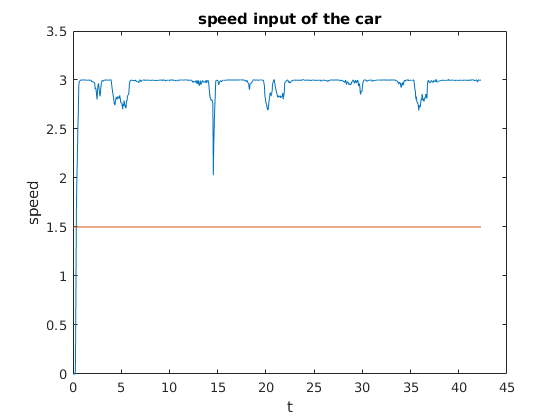

% Let's look at the angle and input data we have 
figure();
plot(time,speed);
hold on;
plot(time, u);
xlabel('t') 
ylabel('speed') 
title("speed input of the car")

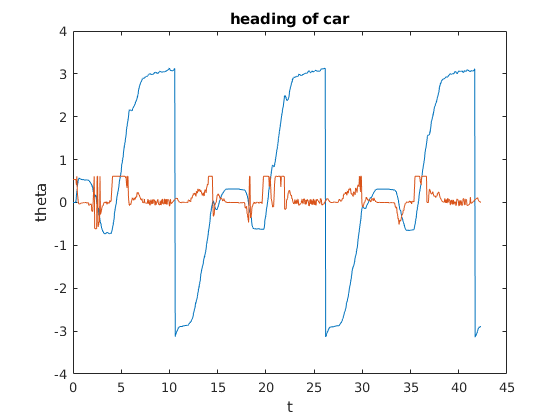

% Let's look at the angle and input data we have 
figure();
plot(time,theta);
hold on;
plot(time, delta);
xlabel('t') 
ylabel('theta') 
title("heading of car")

% Let's try the system identification now

% specify the initial parameters
 ca = 1.633;
 cm = 0.2; 
 ch =4;
 lf = 0.225;
 lr = 0.225;

% not sure why they call it order
% it species the number of model outputs
% the model inputs, and states
% so for us its 2 inputs, 4 outputs, 4 states

order         = [3 2 4];
parameters    = {ca,cm,ch,lf,lr};
initial_states = [0; 0;0;0];
Ts = 0;
nonlinear_model = idnlgrey('bicycle_model',order,parameters,initial_states,Ts);
setpar(nonlinear_model,'Fixed',{false, false,false,false,false});

% Do the estimation 
opt = nlgreyestOptions;
opt.Display = 'Full';
opt.SearchOptions.FunctionTolerance = 1e-10

Option set for the nlgreyest command:

       GradientOptions: [1×1 idoptions.NumericalGradient]
               Display: 'full'
        Regularization: [1×1 struct]
          SearchMethod: 'auto'
         SearchOptions: [1×1 idoptions.search.lsqnonlin]
          OutputWeight: []
    EstimateCovariance: 1
              Advanced: [1×1 struct]

Description of options


opt.SearchOptions.MaxIterations = 10000;
nonlinear_model = nlgreyest(data,nonlinear_model,opt);

% get the parameters
b_est = nonlinear_model.Parameters

b_est = 5×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


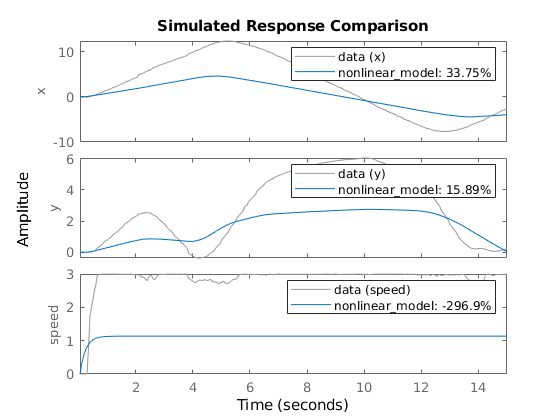

% compare the learned model to the data 
figure();
compare(data,nonlinear_model)